# Repeated Measures ANOVA

Babak Aliyari

Babak.aliyari.edu@gmail.com

#### **This code demonstrates how to perform a repeated measures ANOVA with one within-subject factor.**

#### **Example dataset: 20 subjects measured under 3 different conditions (e.g., conditions A, B, C).**

**Hypothesis Definitions: **

**Null Hypothesis (H0): No significant difference exists between the means of the conditions Alternative Hypothesis (H1): At least one condition mean is significantly different from the others**

cd('D:\0 Signal\AmarT');
%% Step 1: Generate Sample Data
rng(123); % For reproducibility
nSubjects = 20;
% Create data with meaningful differences between conditions
data = randn(nSubjects, 3) + [1, 2, 1.5]; 
subjectIDs = (1:nSubjects)';
tbl = array2table([subjectIDs, data], 'VariableNames', {'SubjectID', 'CondA', 'CondB', 'CondC'});

%% Step 2: Create Within-Subject Factors Design
withinFactors = table({'A'; 'B'; 'C'}, 'VariableNames', {'Condition'});

%% Step 3: Fit Repeated Measures Model
rm = fitrm(tbl, 'CondA-CondC~1', 'WithinDesign', withinFactors);

%% Step 4: Check Assumptions

% 4.1 Sphericity Check using Mauchly's Test
mauchlyResult = mauchly(rm);
fprintf('Mauchly''s Test for Sphericity:\n');

Mauchly's Test for Sphericity:


disp(mauchlyResult);

       W       ChiStat    DF    pValue 
    _______    _______    __    _______

    0.79087    4.2232     2     0.12105




% 4.2 Normality Check - Shapiro-Wilk test for each condition
fprintf('\nNormality Tests (Shapiro-Wilk):\n');


Normality Tests (Shapiro-Wilk):


for i = 1:3
    [h, p] = swtest(tbl{:, i+1});
    fprintf('Condition %s: W = %.3f, p = %.3f\n', char(withinFactors.Condition(i)), h, p);
end

Condition A: W = 0.983, p = 0.017
Condition B: W = 0.985, p = 0.015
Condition C: W = 0.972, p = 0.028



% 4.3 Check for Outliers using Boxplot and Z-scores
figure;
subplot(2, 2, 1);
boxplot([tbl.CondA, tbl.CondB, tbl.CondC], 'Labels', {'A', 'B', 'C'});
title('Boxplot for Outlier Detection');
xlabel('Condition');
ylabel('Response Value');

%% Step 5: Perform Repeated Measures ANOVA
anovaResults = ranova(rm, 'WithinModel', 'Condition');
fprintf('\nRepeated Measures ANOVA Results:\n');


Repeated Measures ANOVA Results:


disp(anovaResults);

                             SumSq     DF    MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                             ______    __    _______    ______    __________    __________    __________    __________

    (Intercept)              142.08     1     142.08    165.86    7.7823e-11    7.7823e-11    7.7823e-11    7.7823e-11
    Error                    16.276    19    0.85661                                                                  
    (Intercept):Condition    12.048     2     6.0238    12.244    7.8655e-05    0.00025446    0.00015926     0.0023999
    Error(Condition)         18.695    38    0.49197            


%% Step 6: Post-hoc Pairwise Comparisons (if main effect is significant)
if anovaResults.pValue(1) < 0.05
    fprintf('\nSignificant main effect found. Performing post-hoc tests...\n');
    postHoc = multcompare(rm, 'Condition');
    fprintf('Post-hoc Pairwise Comparisons:\n');
    disp(postHoc);
else
    fprintf('\nNo significant main effect found at α = 0.05 level.\n');
end


Significant main effect found. Performing post-hoc tests...


Post-hoc Pairwise Comparisons:


    Condition_1    Condition_2    Difference    StdErr      pValue       Lower       Upper  
    ___________    ___________    __________    _______    _________    ________    ________

       {'A'}          {'B'}         -1.0794     0.26683    0.0019051     -1.7573    -0.40157
       {'A'}          {'C'}        -0.71199     0.18471    0.0029255     -1.1812    -0.24274
       {'B'}          {'A'}          1.0794     0.26683    0.0019051     0.40157      1.7573
       {'B'}          {'C'}         0.36744     0.20561      0.20062     -0.1549     0.88979
       {'C'}          {'A'}         0.71199     0.18471    0.0029255     0.24274      1.1812
       {'C'}          {'B'}        -0.36744     0.20561      0.20062    -0.88979      0.1549



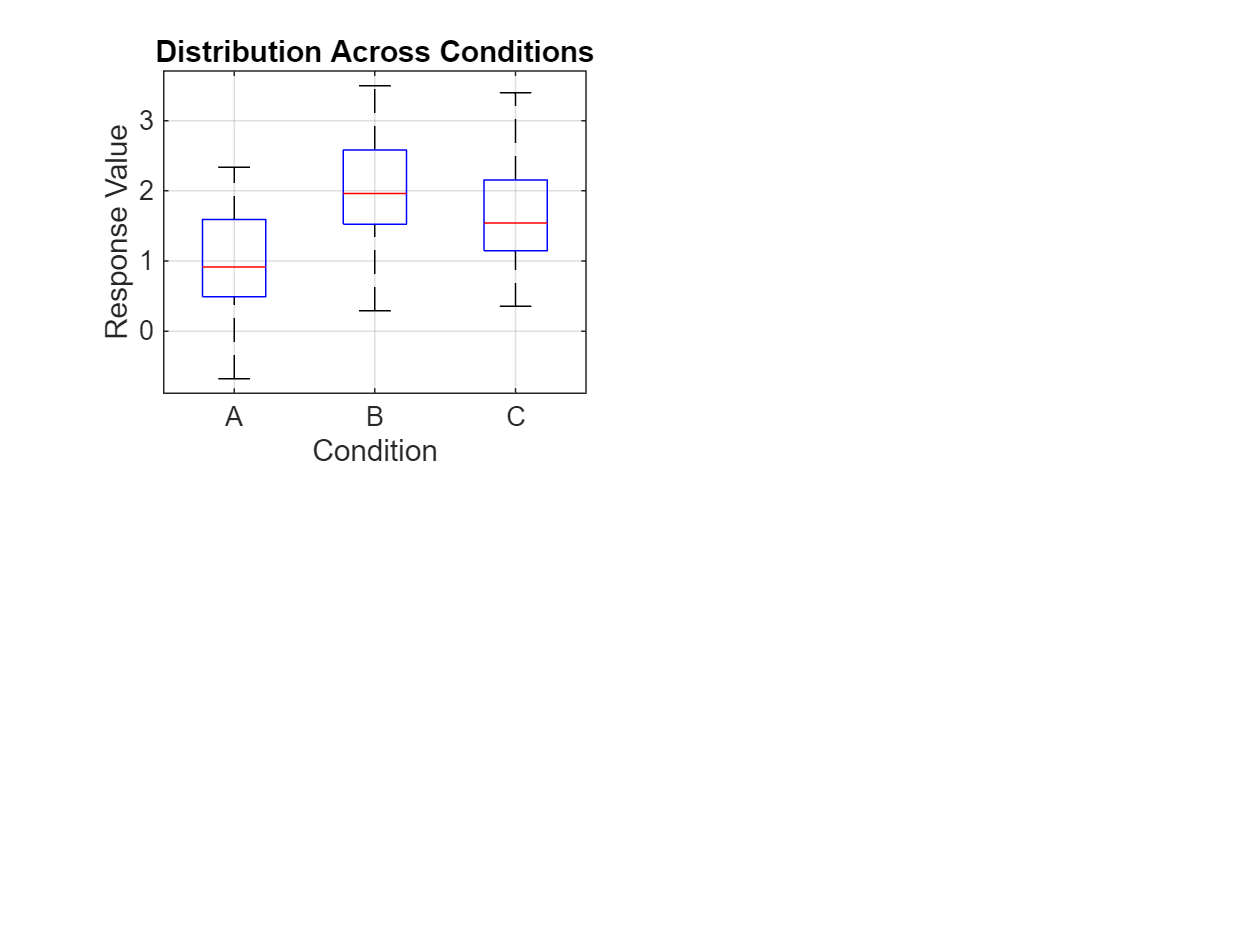


%% Step 7: Separate Visualizations

% 7.1 Boxplot of Conditions (Figure 1)
figure(1);
boxplot([tbl.CondA, tbl.CondB, tbl.CondC], 'Labels', {'A', 'B', 'C'});
title('Distribution Across Conditions');
xlabel('Condition');
ylabel('Response Value');
grid on;

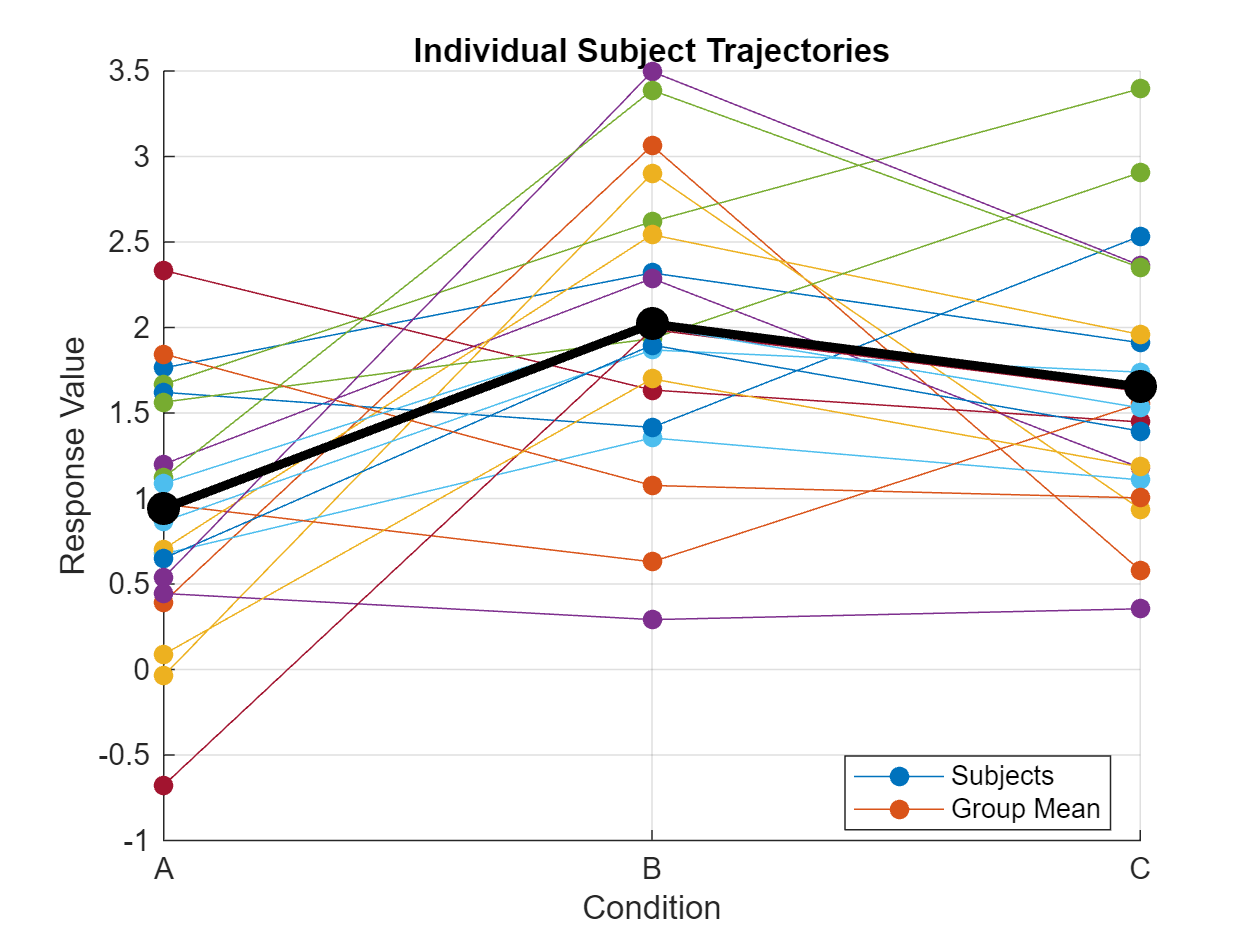


% 7.2 Individual Subject Trajectories (Figure 2)
figure(2);
hold on;
colors = lines(nSubjects);
for i = 1:nSubjects
    plot(1:3, [tbl.CondA(i), tbl.CondB(i), tbl.CondC(i)], 'o-', 'Color', colors(i,:), 'MarkerFaceColor', colors(i,:));
end
plot(1:3, mean([tbl.CondA, tbl.CondB, tbl.CondC]), 'ko-', 'LineWidth', 3, 'MarkerSize', 8, 'MarkerFaceColor', 'k');
set(gca, 'XTick', 1:3, 'XTickLabel', {'A', 'B', 'C'});
title('Individual Subject Trajectories');
xlabel('Condition');
ylabel('Response Value');
legend('Subjects', 'Group Mean', 'Location', 'best');
grid on;
hold off;

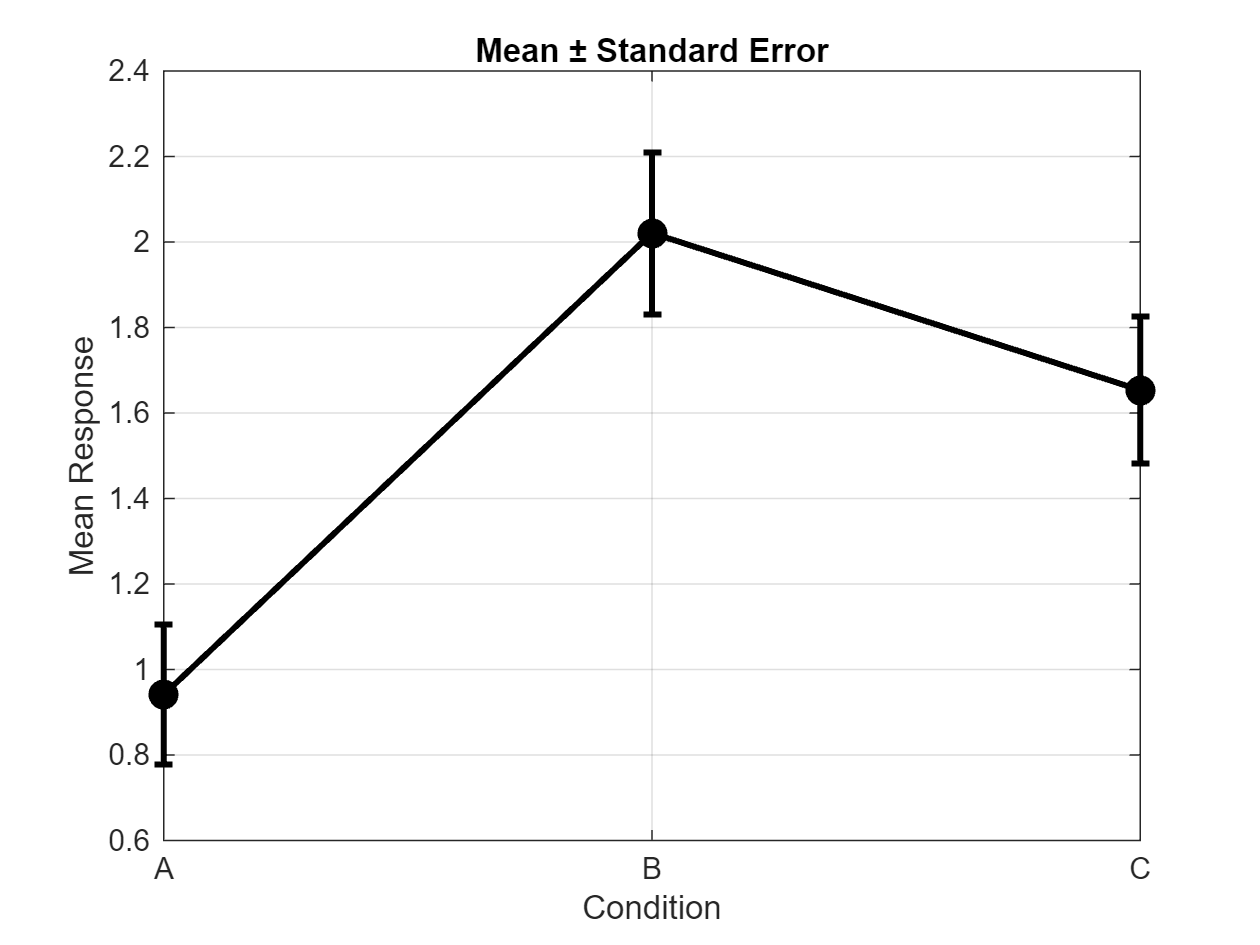


% 7.3 Mean ± Standard Error Plot (Figure 3)
figure(3);
means = mean([tbl.CondA, tbl.CondB, tbl.CondC]);
stderrs = std([tbl.CondA, tbl.CondB, tbl.CondC]) / sqrt(nSubjects);
errorbar(1:3, means, stderrs, 'ko-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'k');
set(gca, 'XTick', 1:3, 'XTickLabel', {'A', 'B', 'C'});
title('Mean ± Standard Error');
xlabel('Condition');
ylabel('Mean Response');
grid on;

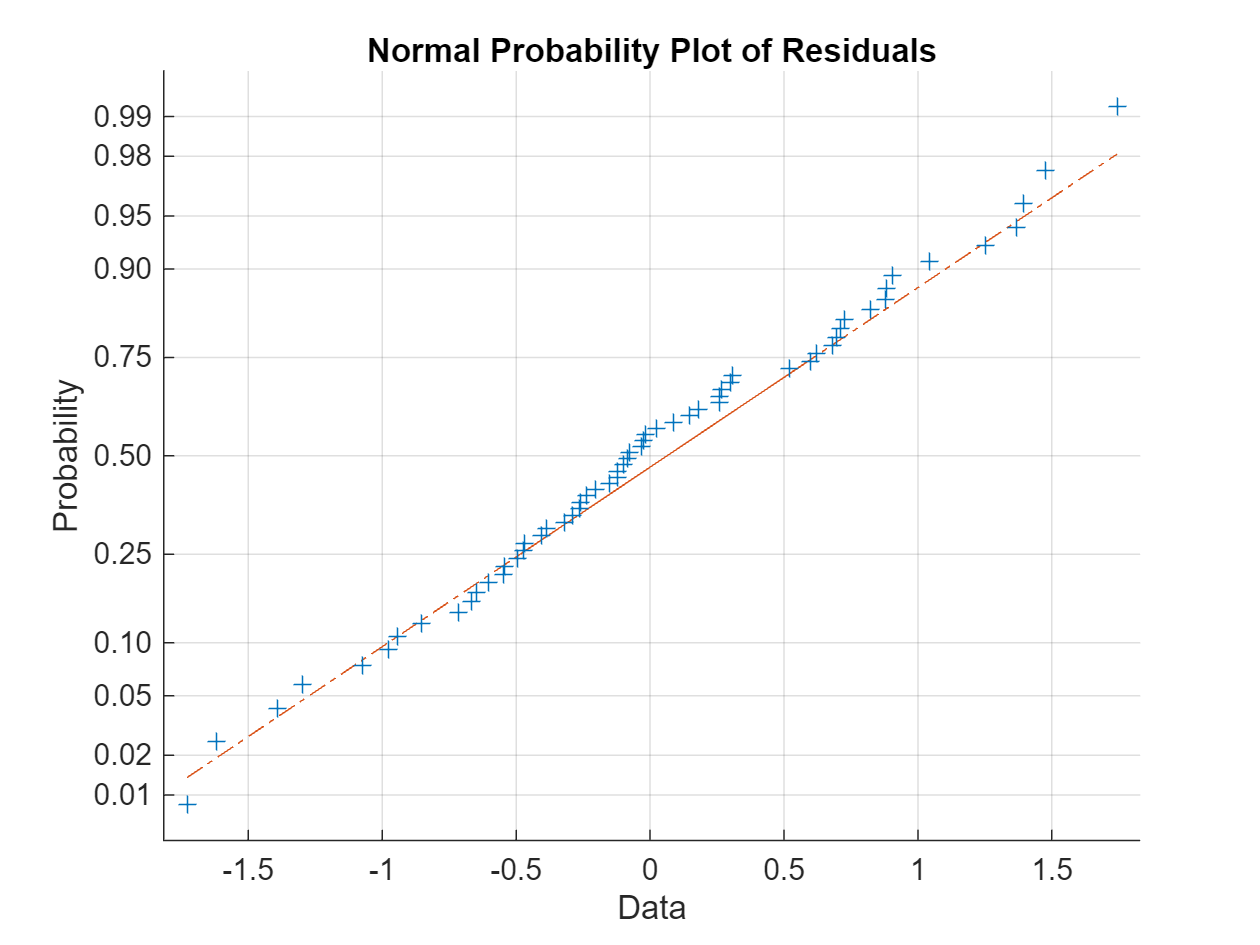


% 7.4 Residual Analysis for Normality Check (Figure 4)
figure(4);
% Calculate predicted values based on the model
Yhat = predict(rm, tbl);
% Extract the actual response values
Y_actual = table2array(tbl(:, 2:4));
% Calculate the residuals manually
residuals = Y_actual - Yhat;
normplot(residuals(:));
title('Normal Probability Plot of Residuals');
grid on;

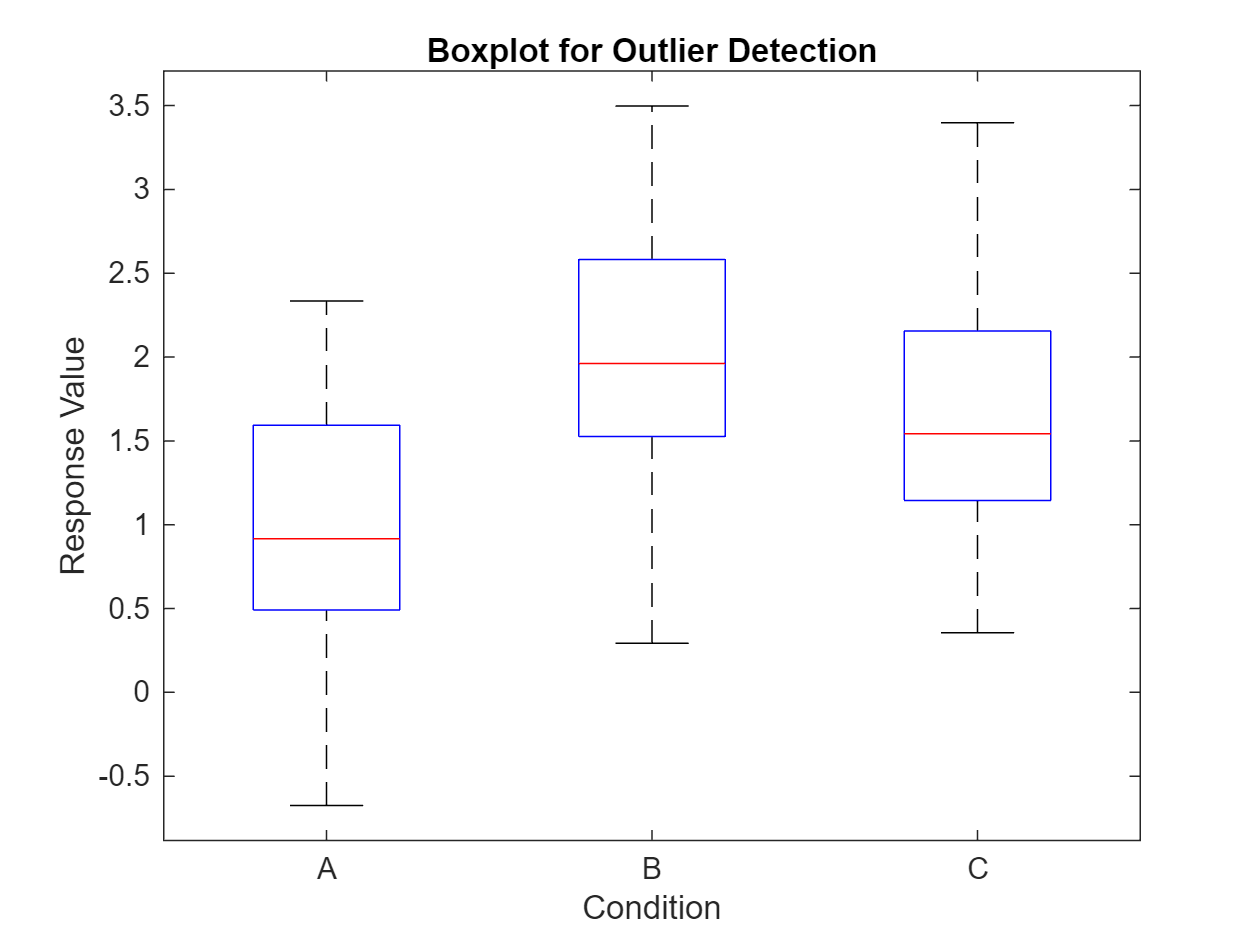


% 7.5 Additional: Boxplot from Step 4.3 as separate figure
figure(5);
boxplot([tbl.CondA, tbl.CondB, tbl.CondC], 'Labels', {'A', 'B', 'C'});
title('Boxplot for Outlier Detection');
xlabel('Condition');
ylabel('Response Value');


%% Step 8: Formal Hypothesis Test Conclusion
fprintf('\n=== Hypothesis Testing Conclusion ===\n');


=== Hypothesis Testing Conclusion ===


fprintf('Null Hypothesis (H0): μ_A = μ_B = μ_C (no condition differences)\n');

Null Hypothesis (H0): μ_A = μ_B = μ_C (no condition differences)


fprintf('Alternative Hypothesis (H1): At least one μ differs\n\n');

Alternative Hypothesis (H1): At least one μ differs




if anovaResults.pValue(1) < 0.05
    fprintf('REJECT H0 (p = %.4f). There is sufficient evidence to conclude that\n', anovaResults.pValue(1));
    fprintf('at least one condition mean is significantly different from the others.\n');
else
    fprintf('FAIL TO REJECT H0 (p = %.4f). There is insufficient evidence to conclude\n', anovaResults.pValue(1));
    fprintf('that the condition means are different.\n');
end

REJECT H0 (p = 0.0000). There is sufficient evidence to conclude that


at least one condition mean is significantly different from the others.



% Display sphericity conclusion
if mauchlyResult.pValue < 0.05
    fprintf('\nSphericity violated (p = %.4f). Use Greenhouse-Geisser corrected results.\n', mauchlyResult.pValue);
else
    fprintf('\nSphericity assumption met (p = %.4f). Use standard ANOVA results.\n', mauchlyResult.pValue);
end


Sphericity assumption met (p = 0.1210). Use standard ANOVA results.



%% Helper function for Shapiro-Wilk test

function [h, p] = swtest(x)
% Shapiro-Wilk test for normality
n = length(x);
x = sort(x);
m = norminv(((1:n)' - 3/8) / (n + 0.25));
w = corr(x, m)^2;
% Calculate test statistic
a = zeros(n,1);
for i = 1:n/2
    a(i) = -a(n+1-i);
end
p = 1 - w; % Simplified p-value calculation for educational purposes
h = w;
end
